# 01 Hands On: Discrete Systems - 2D spring system - Part 2

Transformation matrix of local degrees of freedom:

$\left\lbrack \begin{array}{c}
u_{1,L} \\
u_{2,L} 
\end{array}\right\rbrack =\underset{\mathbf{T}}{\underbrace{\left\lbrack \begin{array}{cccc}
\cos \left(\alpha \;\right) & \sin \left(\alpha \right) & 0 & 0\\
0 & 0 & \cos \left(\alpha \right) & \sin \left(\alpha \;\right)
\end{array}\right\rbrack } } \;\left\lbrack \begin{array}{c}
u_{1,G} \\
v_{1,G} \\
u_{2,G} \\
v_{2,G} 
\end{array}\right\rbrack$     or    $\left\lbrack \begin{array}{c}
u_{1,G} \\
v_{1,G} \\
u_{2,G} \\
v_{2,G} 
\end{array}\right\rbrack =\underset{{\mathbf{T}}^{-1} ={\mathbf{T}}^T }{\underbrace{\left\lbrack \begin{array}{cc}
\cos \left(\alpha \;\right) & 0\\
\sin \left(\alpha \;\right) & 0\\
0 & \cos \left(\alpha \right)\\
0 & \sin \left(\alpha \;\right)
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
u_{1,L} \\
u_{2,L} 
\end{array}\right\rbrack$

## Spring system from lecture

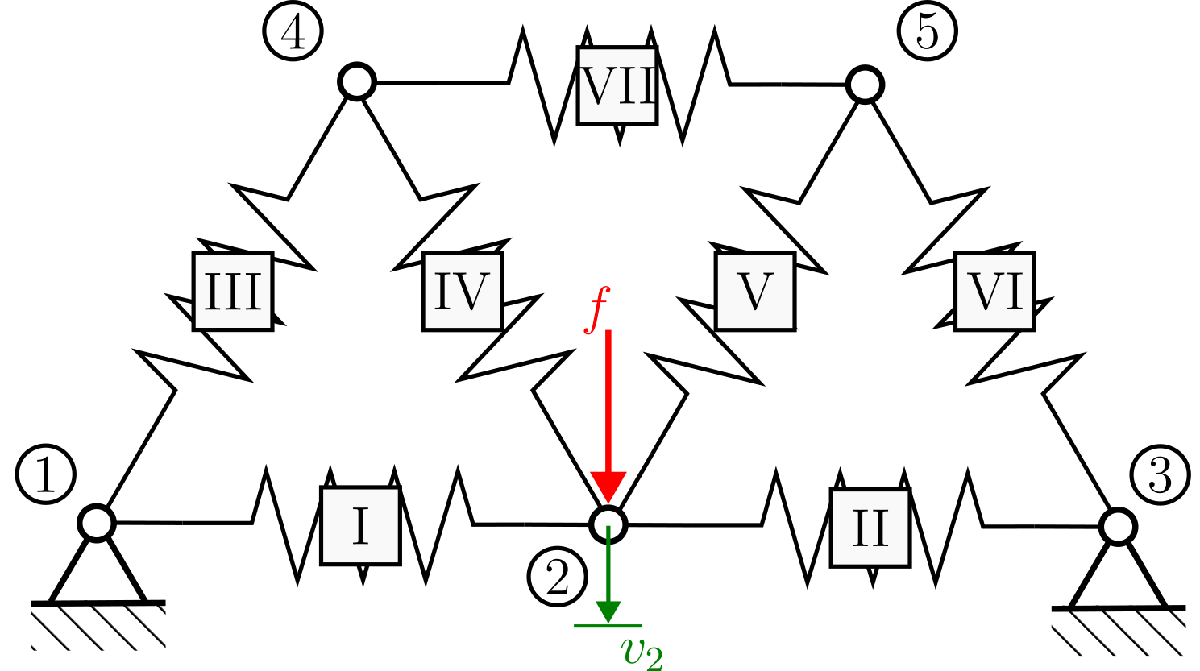

clear all; clc; close all;

% Set up spring stiffness matrixes and assemble global stiffness matrix
connectivity = [1 2 3 4; 3 4 5 6; 1 2 7 8; 7 8 3 4; 3 4 9 10; 9 10 5 6; 7 8 9 10];
angles = [0, 0, 60, -60, 60, -60, 0];

KEL = [1 -1; -1 1];
k = 20;
K = zeros(10);
for spring = 1 : 7
    edof = connectivity(spring, :);
    TE = transformationMatrix(angles(spring));
    KE = k * TE' * KEL * TE;
    K(edof, edof) = K(edof, edof) + KE;
end

% Force vector and solution
u = zeros(10, 1);
f = zeros(10, 1);
f(4) = -1;
fixeddof = [1, 2, 6];
freedof = setdiff(1 : 10, fixeddof)

freedof =      3     4     5     7     8     9    10


u(freedof) = K(freedof, freedof) \ f(freedof)

u =          0
         0
    0.0144
   -0.0917
    0.0289
         0
    0.0289
   -0.0500
    0.0000
   -0.0500


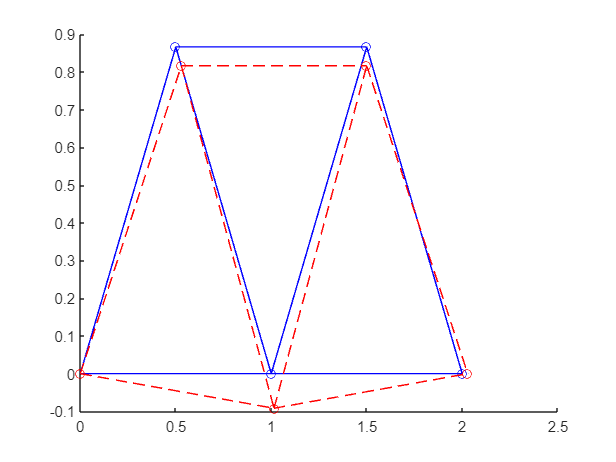

% Visualization
x0 = [0, 0; 1, 0; 2, 0; cosd(60), sind(60); cosd(60) + 1, sind(60)];

plotSpringSystem(x0, connectivity);
plotSpringSystem(x0 + transpose(reshape(u, 2, 5)), connectivity, 'red')

function plotSpringSystem(x, connectivity, color)
    % Plot lines between two points of the given nodal positions using given connectivity
    % INPUT
    %   x (array)               Nodal coordinates in format [x1, y1; x2 y2; ...] 
    %   connectivity (array)    Array of nodes per spring
    %   color (string/array)    OPTIONAL Color for spring in plot
    if nargin < 3
        color = 'blue';        % Default color: blue
        lineStyle = '-o';   % Default linestyle
    else
        lineStyle = '--o';
    end
    % Reshape nodes in order to be able to use the DOF indicies from the connectivity
    % matrix to extract the correct nodal coordinates via linear indexing.
    nodes = x';

    hold on;
    for spring = 1 : size(connectivity, 1)
        springConnectivity = connectivity(spring, :);
        plot(nodes(springConnectivity([1, 3])), nodes(springConnectivity([2, 4])), lineStyle, Color = color)
    end
    hold off;
end

function T = transformationMatrix(angle)
    % Returns transformation matrix for two local degrees of freedom to global 2D system
    % INPUT
    %   angle (float)   Rotation angle in degrees
    T = [cosd(angle), sind(angle), 0, 0;
        0, 0, cosd(angle), sind(angle)];
end
